# Εξαμηνιαία Εργασία Ρομποτικής

## Τοποθέτηση Πλαισίων

syms q1 q2 q3 l0 l1 l2 l3
dhaxis = ['z','z','x','x'];
% move from the starting frame to the A'-th frame
A01 = (frame_transform(dhaxis, [0 l0 0 pi/2]))

$$A01 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% move from 0th frame to an intermediate frame
A12 = simplify(frame_transform(dhaxis, [q1 0 0 -pi/2]))

$$A12 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% move from the intermediate frame to the first frame
A23 = (frame_transform(dhaxis, [q2 l1 l2 0]))

$$A23 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & l_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% move from the first to the second frame
A3E = frame_transform(dhaxis, [q3 0 l3 0])

$$A3E = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & l_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & l_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Ευθεία κινηματική εξίσωση

% forward kinematic equation
A = A01*A12*A23*A3E;
A = simplify(A)

$$A = \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sin\left(q_{2}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & 0 & l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & l_{0}+l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Ιακωβιανή Μήτρα

% move from start to first frame
% A01 = AAA*AA0*A0E*AE1

$$A01 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% move from start to second frame
A02 = simplify(A01*A12)

$$A02 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ 0 & 1 & 0 & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% move from start to the actor
A03 = simplify(A02*A23)

$$A03 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\sin\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & l_{2}\,\sin\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{1}\right) & l_{0}+l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A0E = simplify(A03*A3E)

$$A0E = \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sin\left(q_{2}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & 0 & l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & l_{0}+l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% setup the calculation of the jacobian
b0 = [0 -1 0]'

b0 =      0
    -1
     0


b1 = mybeta(A02)

$$b1 = \left(\begin{array}{c} -\sin\left(q_{1}\right)\\ 0\\ \cos\left(q_{1}\right) \end{array}\right)$$

b2 = mybeta(A03)

$$b2 = \left(\begin{array}{c} -\sin\left(q_{1}\right)\\ 0\\ \cos\left(q_{1}\right) \end{array}\right)$$

r0 = simplify(myrho(A0E, A01))

$$r0 = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\\ l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) \end{array}\right)$$

r1 = simplify(myrho(A0E, A02))

$$r1 = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\\ l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) \end{array}\right)$$

r2 = simplify(myrho(A0E, A03))

$$r2 = \left(\begin{array}{c} l_{3}\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ l_{3}\,\sin\left(q_{2}+q_{3}\right)\\ l_{3}\,\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) \end{array}\right)$$

% calculate the jacobian (all joints are rotational)
Jl0 = simplify(cross(b0,r0))

$$Jl0 = \left(\begin{array}{c} l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-l_{1}\,\cos\left(q_{1}\right)\\ 0\\ l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) \end{array}\right)$$

Jl1 = simplify(cross(b1,r1))

$$Jl1 = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right)\\ l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)\\ -\sin\left(q_{1}\right)\,\left(l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right) \end{array}\right)$$

Jl2 = simplify(cross(b2,r2))

$$Jl2 = \left(\begin{array}{c} -l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ l_{3}\,\cos\left(q_{2}+q_{3}\right)\\ -l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) \end{array}\right)$$

Jac = [Jl0 Jl1 Jl2;
        b0  b1  b2];
Jac = simplify(Jac)

$$Jac = \begin{array}{l} \left(\begin{array}{ccc} l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-l_{1}\,\cos\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sigma_{1} & -l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ 0 & \sigma_{2}+l_{2}\,\cos\left(q_{2}\right) & \sigma_{2}\\ l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\sin\left(q_{1}\right)\,\sigma_{1} & -l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & -\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\\ -1 & 0 & 0\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\\ \sigma_{2}=l_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

## Αντίστροφο Διαφορικό Κινηματικό Μοντέλο ως προς γραμμική ταχύτητα

Jac_v = Jac(1:3, 1:3)

$$Jac\_v = \begin{array}{l} \left(\begin{array}{ccc} l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-l_{1}\,\cos\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sigma_{1} & -l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ 0 & \sigma_{2}+l_{2}\,\cos\left(q_{2}\right) & \sigma_{2}\\ l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\sin\left(q_{1}\right)\,\sigma_{1} & -l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\\ \sigma_{2}=l_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

syms q1d q2d q3d real
syms p1d p2d p3d real
q_dot = [q1d q2d q3d];
detJv = det(Jac_v);
detJv = simplify(detJv)

$$detJv = l_{2}\,l_{3}\,\left(l_{3}\,\sin\left(q_{2}\right)\,{\cos\left(q_{3}\right)}^{2}+l_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\cos\left(q_{3}\right)-l_{3}\,\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)$$

simplify(subs(Jac_v, {q3}, {0}))

$$ans = \left(\begin{array}{ccc} -l_{1}\,\cos\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-l_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(l_{2}+l_{3}\right) & -l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & \cos\left(q_{2}\right)\,\left(l_{2}+l_{3}\right) & l_{3}\,\cos\left(q_{2}\right)\\ l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(l_{2}+l_{3}\right) & -l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) \end{array}\right)$$

simplify(subs(Jac_v, {q3}, {pi}))

$$ans = \left(\begin{array}{ccc} l_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-l_{1}\,\cos\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(l_{2}-l_{3}\right) & l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & \cos\left(q_{2}\right)\,\left(l_{2}-l_{3}\right) & -l_{3}\,\cos\left(q_{2}\right)\\ l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)-l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(l_{2}-l_{3}\right) & l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) \end{array}\right)$$

## Αντίστροφο Γεωμετρικό Μοντέλο

% αχρηστο
n = A(1:3, 1);
o = A(1:3, 2);
a = A(1:3, 3);
p = A(1:3, 4);

## Definition of joint lengths

format long
l(1) = 15.0; % joint lengths
l(2) = 12.0;
l(3) = 15.0;
l(4) = 20.0;

## Definition of linear trajectory

dt = 0.01; % sampling period
Tf = 10.0; % duration of trajectory
t = 0:dt:Tf;
x_initial = 20.0; % starting x position
x_desired = 10.0; % final x position
y_initial = 15.0; % starting y position
y_desired = 20.0; % final y position
z_initial = 40.0; % movement on the xy plane
z_desired = 40.0; % so z remains constant

lambda_x = (x_desired-x_initial)/Tf; % rate of change x axis
lambda_y = (y_desired-y_initial)/Tf; % rate of change y axis
kmax = Tf/dt + 1; % number of steps
xd = zeros(1, kmax); % initialization of x vector
yd = zeros(1, kmax); % initialization of y vector
zd = z_initial*ones(1, kmax);
xd(1) = x_initial;
yd(1) = y_initial;
for k=2:kmax
    xd(k) = xd(k-1) + lambda_x*dt;
    yd(k) = yd(k-1) + lambda_y*dt;
end

## Inverse Kinematics

px = xd; py = yd; pz = zd;
sigma = sqrt(px.^2 + (pz-l(1)).^2 - l(2)^2)

sigma =   34.641016151377549  34.635243611096485  34.629472996278764  34.623704307887103  34.617937546884562  34.612172714234504  34.606409810900637  34.600648837846947  34.594889796037791  34.589132686437793  34.583377510011935  34.577624267725497  34.571872960544084  34.566123589433616  34.560376155360338  34.554630659290794  34.548887102191856  34.543145485030728  34.537405808774906  34.531668074392215  34.525932282850796  34.520198435119092  34.514466532165876  34.508736574960238  34.503008564471571  34.497282501669581  34.491558387524307  34.485836223006082  34.480116009085556  34.474397746733707  34.468681436921806  34.462967080621453  34.457254678804546  34.451544232443311  34.445835742510269  34.440129209978259  34.434424635820442  34.428722021010273  34.423021366521525  34.417322673328293  34.411625942404953  34.405931174726220  34.400238371267100  34.394547533002921  34.388858660909314  34.383171755962202  34.377486819137857  34.371803851412821  34.366122853763954  34.3604438

% the qd3 has been mistakenly computed as
% acos((py.^2+sigma.^2-(l(3)^2+l(4)^2))./(l(3)*l(4)))
% in the report. notice the missing factor of two in the
% denominator. the correct formula is used in this simulation.
qd3 = acos((py.^2+sigma.^2-(l(3)^2+l(4)^2))./(2*l(3)*l(4)))

qd3 =    0.674130506667315   0.674630725966471   0.675130132615486   0.675628728258858   0.676126514533389   0.676623493068246   0.677119665484997   0.677615033397672   0.678109598412794   0.678603362129440   0.679096326139276   0.679588492026613   0.680079861368443   0.680570435734490   0.681060216687251   0.681549205782048   0.682037404567062   0.682524814583378   0.683011437365039   0.683497274439078   0.683982327325562   0.684466597537639   0.684950086581580   0.685432795956811   0.685914727155966   0.686395881664927   0.686876260962852   0.687355866522233   0.687834699808924   0.688312762282183   0.688790055394715   0.689266580592708   0.689742339315874   0.690217332997484   0.690691563064410   0.691165030937162   0.691637738029923   0.692109685750590   0.692580875500811   0.693051308676016   0.693520986665462   0.693989910852263   0.694458082613430   0.694925503319901   0.695392174336585   0.695858097022388   0.696323272730255   0.696787702807200   0.697251388594344   0.697714331

c3 = cos(qd3); s3 = sin(qd3);
qd1 = atan2(pz-l(1), px)-atan2(l(2), sigma)

qd1 =    0.701758821744515   0.701945215492308   0.702131681407899   0.702318219514401   0.702504829834919   0.702691512392549   0.702878267210374   0.703065094311472   0.703251993718907   0.703438965455736   0.703626009545005   0.703813126009751   0.704000314873000   0.704187576157769   0.704374909887066   0.704562316083888   0.704749794771220   0.704937345972041   0.705124969709318   0.705312666006007   0.705500434885054   0.705688276369398   0.705876190481964   0.706064177245668   0.706252236683416   0.706440368818105   0.706628573672618   0.706816851269832   0.707005201632611   0.707193624783808   0.707382120746268   0.707570689542823   0.707759331196297   0.707948045729500   0.708136833165235   0.708325693526291   0.708514626835450   0.708703633115479   0.708892712389138   0.709081864679175   0.709271090008325   0.709460388399315   0.709649759874860   0.709839204457664   0.710028722170419   0.710218313035809   0.710407977076503   0.710597714315162   0.710787524774435   0.710977408

c1 = cos(qd1); s1 = sin(qd1);
% qd2 = atan2((pz-l(1)-l(2)*c1)./(s1), py)-atan2(l(3)+l(4)*c3, l(4)*s3)
% qd2_pan = atan2(py, sigma)+atan2(l(3)+l(4)*c3, l(4)*s3)
qd2 = asin(((l(3)+l(4).*c3)./(l(4).*s3).*py-(pz-l(1)-l(2).*c1)./(s1))./(((l(3)+l(4).*c3).^2)./(l(4).*s3)+l(4).*s3))

qd2 =    0.071572601763935   0.071504819108666   0.071437454461951   0.071370506956731   0.071303975729750   0.071237859921535   0.071172158676369   0.071106871142266   0.071041996470953   0.070977533817841   0.070913482342006   0.070849841206162   0.070786609576643   0.070723786623377   0.070661371519867   0.070599363443164   0.070537761573846   0.070476565096005   0.070415773197211   0.070355385068502   0.070295399904355   0.070235816902671   0.070176635264751   0.070117854195274   0.070059472902280   0.070001490597144   0.069943906494564   0.069886719812531   0.069829929772317   0.069773535598451   0.069717536518699   0.069661931764049   0.069606720568685   0.069551902169974   0.069497475808441   0.069443440727756   0.069389796174710   0.069336541399200   0.069283675654209   0.069231198195789   0.069179108283036   0.069127405178085   0.069076088146079   0.069025156455159   0.068974609376444   0.068924446184011   0.068874666154883   0.068825268569007   0.068776252709238   0.068727617

c2 = cos(qd2); s2 = sin(qd2);

## Cartesian Coordinates

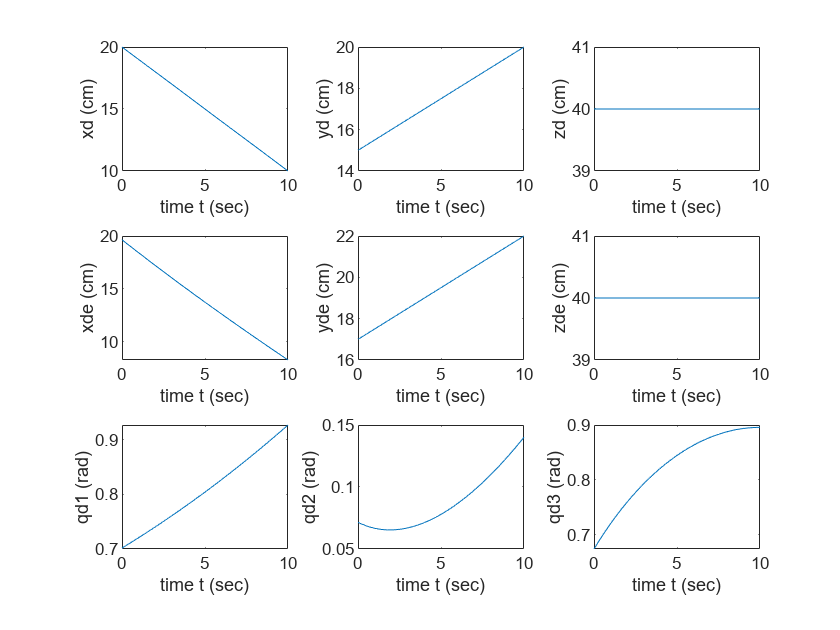

% base remains still
xdbase = zeros(1, kmax);
ydbase = zeros(1, kmax);
zdbase = zeros(1, kmax);

% first joint remains still but is elevated by l(1)
xd1 = xdbase;
yd1 = ydbase;
zd1 = ones(1, kmax).*l(1);

% second joint can move due to the first joint.
% however, it can only move at the xz plane.
xd2 = xdbase - l(2).*s1;
yd2 = ydbase;
zd2 = zd1 + l(2).*c1;

% third joint can move due to the first two joints.
% it can move on the y axis as well.
xd3 = xd2 + l(3).*c1.*c2;
yd3 = yd2 + l(3).*s2;
zd3 = zd2 + l(3).*s1.*c2;

% end effect tool
xde = xd3 + l(4).*c1.*c2 + l(4).*c3 - 20;
yde = yd3 + l(3).*(sin(qd2+qd3)) + 2;
% rounding because the printing gets messed up otherwise.
% it doesn't actually change the value.
zde = round(zd3 + l(4).*s1.*(cos(qd2+qd3)));

fig1 = figure;
subplot(3,3,1);
plot(t,xd);
ylabel('xd (cm)');
xlabel('time t (sec)');
subplot(3,3,2);
plot(t,yd);
ylabel('yd (cm)');
xlabel('time t (sec)');
subplot(3,3,3);
plot(t,zd);
ylabel('zd (cm)'); 
xlabel('time t (sec)');

subplot(3,3,4);
plot(t,xde);
ylabel('xde (cm)');
xlabel('time t (sec)');
subplot(3,3,5);
plot(t,yde);
ylabel('yde (cm)');
xlabel('time t (sec)');
subplot(3,3,6);
plot(t,zde);
ylabel('zde (cm)'); 
xlabel('time t (sec)'); 

subplot(3,3,7); 
plot(t,qd1); 
ylabel('qd1 (rad)'); 
xlabel('time t (sec)');  
subplot(3,3,8); 
plot(t,qd2); 
ylabel('qd2 (rad)'); 
xlabel('time t (sec)');  
subplot(3,3,9); 
plot(t,qd3); 
ylabel('qd3 (rad)'); 
xlabel('time t (sec)');

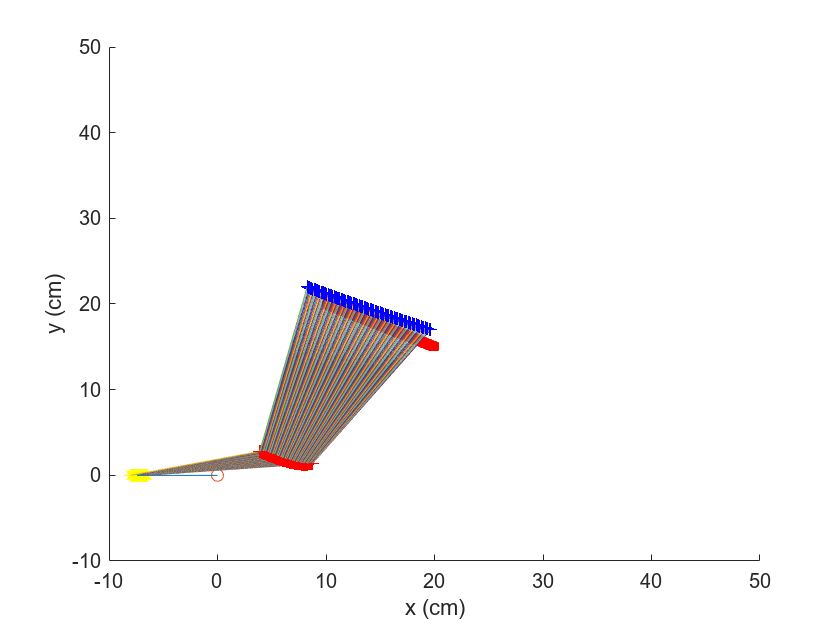

fig2 = figure;
axis([-10 50 -10 50])
axis on
hold on 
xlabel('x (cm)'); 
ylabel('y (cm)'); 
plot(xd,yd,'rs'); 
dtk=10; %% plot robot position every dtk samples, to animate its motion 
plot(0,0,'o');
for tk=1:dtk:kmax    %%% 	
   pause(0.01);	%% pause motion to view successive robot configurations
   % plot([xd1(tk)],[yd1(tk)],'o');    
   plot([xd1(tk),xd2(tk)],[yd1(tk),yd2(tk)]);	
   plot([xd2(tk)],[yd2(tk)],'y*');
   plot([xd2(tk),xd3(tk)],[yd2(tk),yd3(tk)]);	
   plot([xd3(tk)],[yd3(tk)],'r+');
   plot([xd3(tk),xde(tk)],[yd3(tk),yde(tk)]);	
   plot([xde(tk)],[yde(tk)],'b+');
end